%wc = 2*pi*50; 
s = tf('s');
H1= 1/(1+(0.000001*s));
H2= -100/((0.000000079*s) +1);
H3= 1000/(1+(0.000000066*s));
H4= 1/(1+(0.0106*s));

Hs = H1*H2*H3*H4

Hs =
 
                            -100000
  ------------------------------------------------------------
  5.527e-23 s^4 + 1.592e-15 s^3 + 1.214e-08 s^2 + 0.0106 s + 1
 
Continuous-time transfer function.




figure
%hold on 

y=bodeplot(Hs)


y =

	resppack.bodeplot



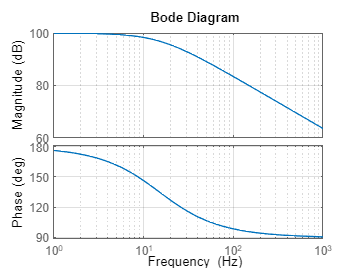

setoptions(y,'FreqUnits','Hz','phaseVisible','on','grid','on');

grid


grid